### Load in Data

clear
load("data.mat");
load("label.mat");

### Prep Data: 

- reshape data to 784 x 500/5000

- grab dimensions

reshaped_imageTrain = reshape(imageTrain, 784, 5000);
reshaped_imageTest = reshape(imageTest, 784, 500);

train_dims = size(reshaped_imageTrain);
test_dims = size(reshaped_imageTest);

## Question 1.

Here, I created a *class_length* variable to store the lengths to calculate alpha in question 2, and I created a *sample_mean* array to store the 784 x 10 sample averages

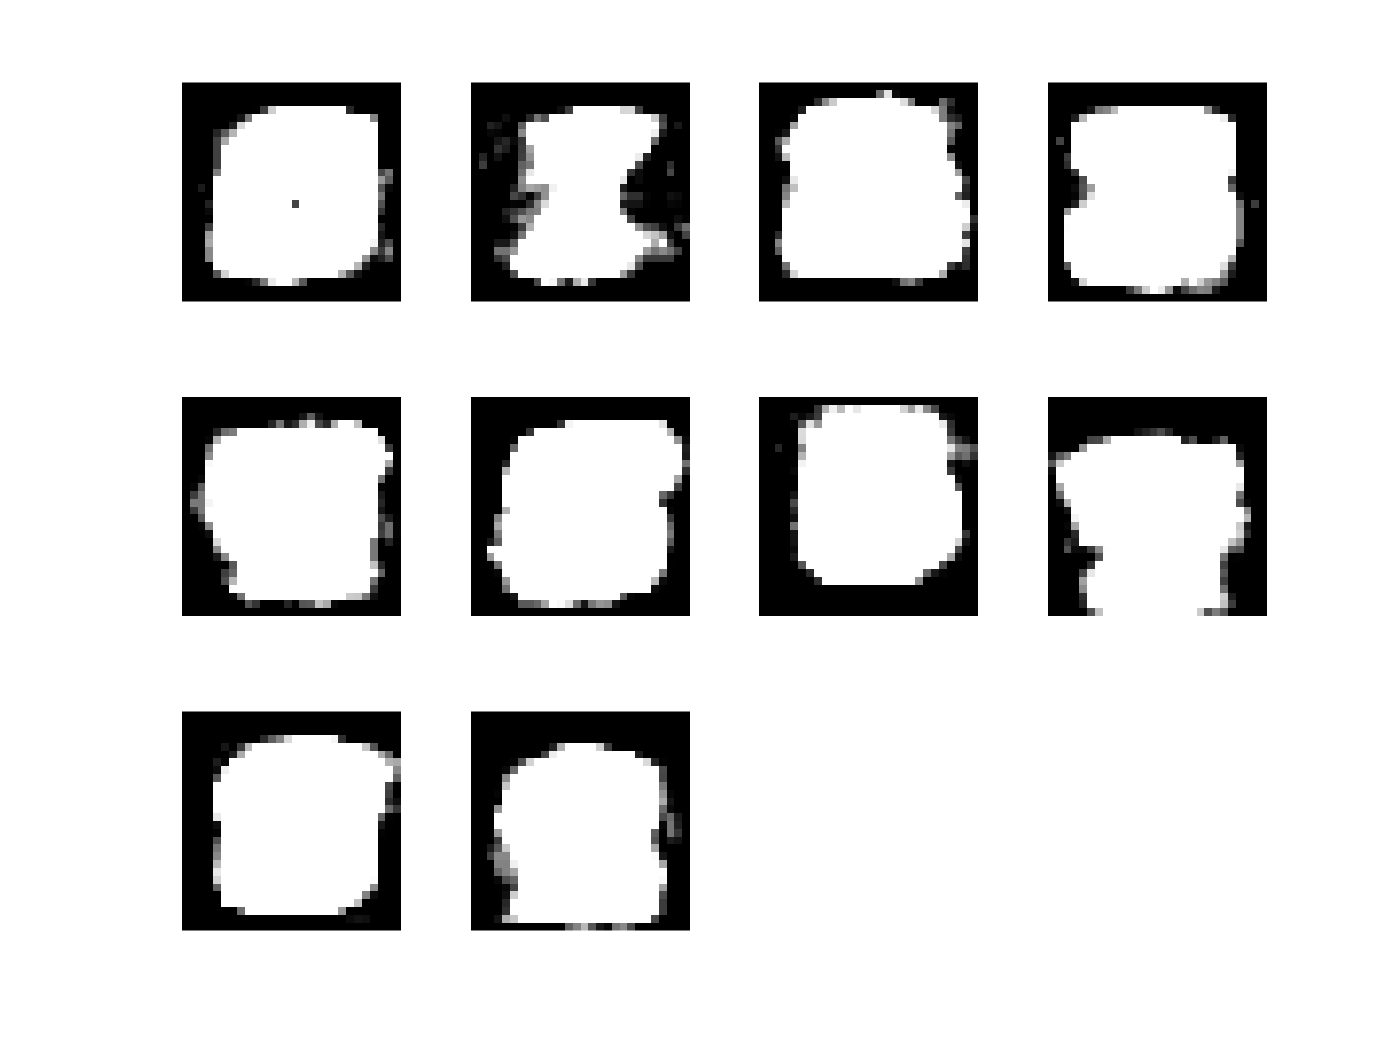

class_length = zeros(1, 10);

sample_mean = zeros(784, 10);
%sample_denominator = sum(reshaped_imageTrain, 2);
%sample_denominator(sample_denominator == 0) = 1;
%for i = 0:9
%    iteration_index = find(labelTrain == i);
%    class_length(i + 1) = length(iteration_index);
%    sample_mean(:, i + 1) = sum(reshaped_imageTrain(:, iteration_index), 2) ./ sample_denominator;
%end

for i = 0:9
    current_indexes = find(labelTrain == i);
    sample_meanDenominator = length(current_indexes);
    sample_mean(:, i + 1) = sum(reshaped_imageTrain(:, current_indexes), 2) / sample_meanDenominator;
end


reshaped_sampleMean = reshape(sample_mean, 28, 28, 10);

% Displaying Tempaltes
subplot(3, 4, 1)
imshow(reshaped_sampleMean(:, :, 1));
subplot(3, 4, 2)
imshow(reshaped_sampleMean(:, :, 2));
subplot(3, 4, 3)
imshow(reshaped_sampleMean(:, :, 3));
subplot(3, 4, 4)
imshow(reshaped_sampleMean(:, :, 4));
subplot(3, 4, 5)
imshow(reshaped_sampleMean(:, :, 5));
subplot(3, 4, 6)
imshow(reshaped_sampleMean(:, :, 6));
subplot(3, 4, 7)
imshow(reshaped_sampleMean(:, :, 7));
subplot(3, 4, 8)
imshow(reshaped_sampleMean(:, :, 8));
subplot(3, 4, 9)
imshow(reshaped_sampleMean(:, :, 9));
subplot(3, 4, 10)
imshow(reshaped_sampleMean(:, :, 10));

## Question 2.

Here, I calculated alpha and the norm to create the Gaussian Classifier using the reduced form stated in lecture, because the covariances are identity. I stored the predicted labels in the variable *predicted_labels*.

alpha = -2 * log10(class_length ./ train_dims(2));
norms = zeros(500, 10);
for i = 0:9
    repeated_sampleMean = repmat(sample_mean(:, i + 1), 1, test_dims(2));
    norms(:, i + 1) = transpose(sum((reshaped_imageTest - repeated_sampleMean) .^ 2));
end

[throw_away ,predicted_labels] = min(norms + repmat(alpha, test_dims(2), 1), [], 2);
predicted_labels = predicted_labels - 1;

## Error Given Class

Here, I calculated the error given the class and placed them in a *given_classError* array.

given_classError = zeros(1, 10);
for i = 0:9
    iteration_index = find(labelTest == i);
    given_size = length(iteration_index);
    pruned_labelTest = labelTest(iteration_index);
    pruned_predictedLabels = predicted_labels(iteration_index);
    given_classError(i + 1) = length(nonzeros(pruned_labelTest - pruned_predictedLabels)) / given_size;
end

## Total Error

Here, I calculated the total error by comparing the predicted labels to the test labels and dividing by the total amount of labels.

total_Error = length(nonzeros(labelTest - predicted_labels)) / test_dims(2);


## Extra Credit

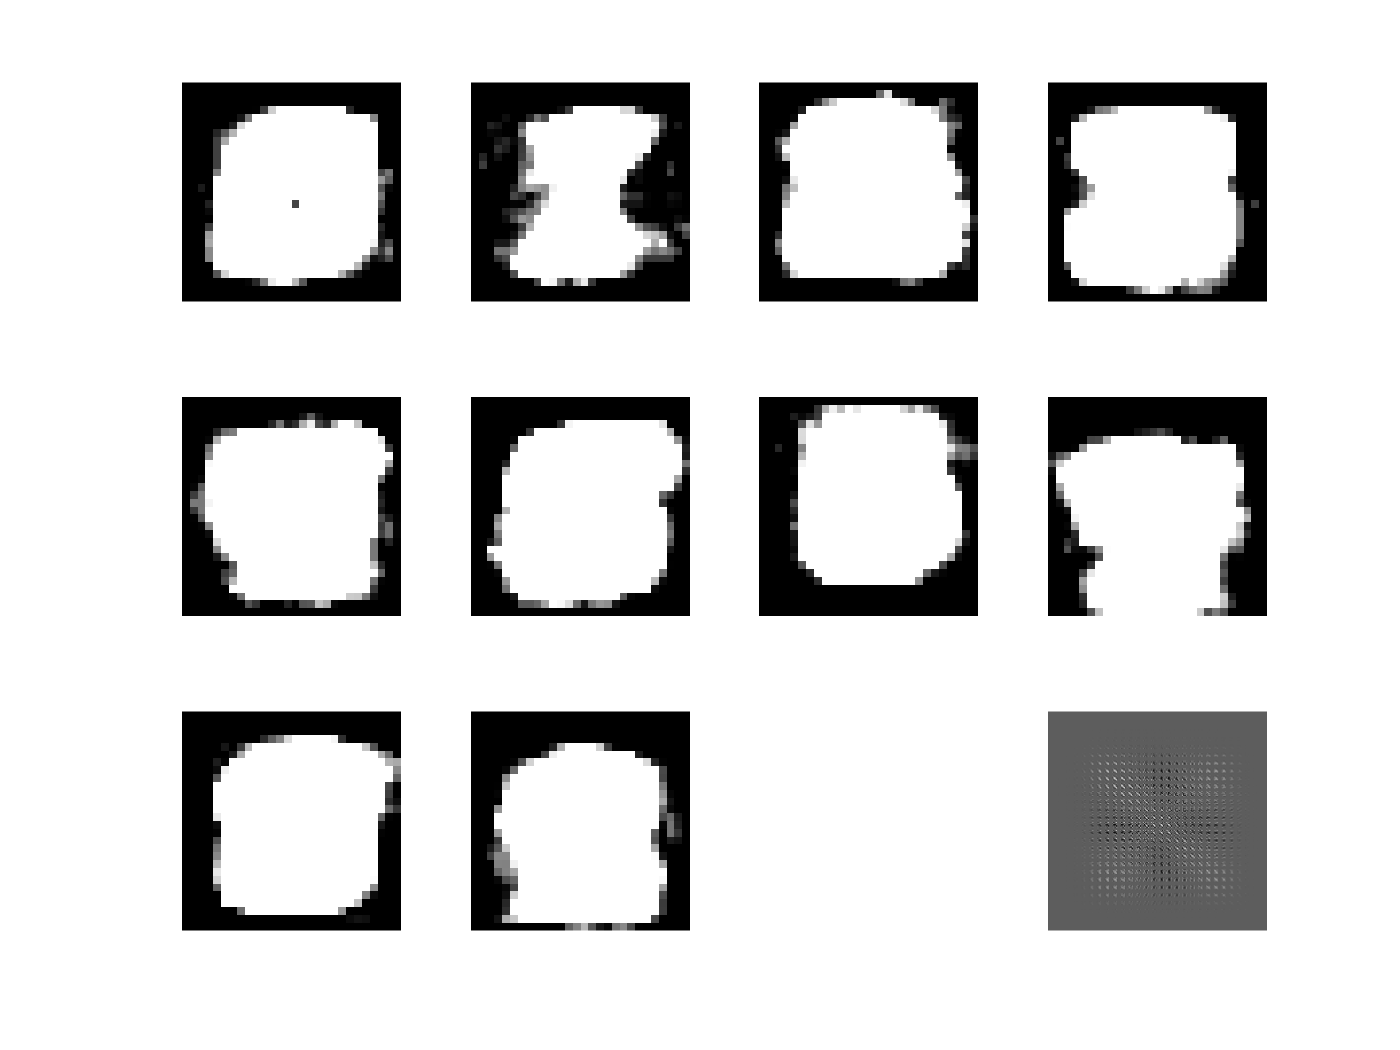

lmatrix = cov(transpose(sample_mean));
subplot(3, 4, 12)
imshow(lmatrix, []);